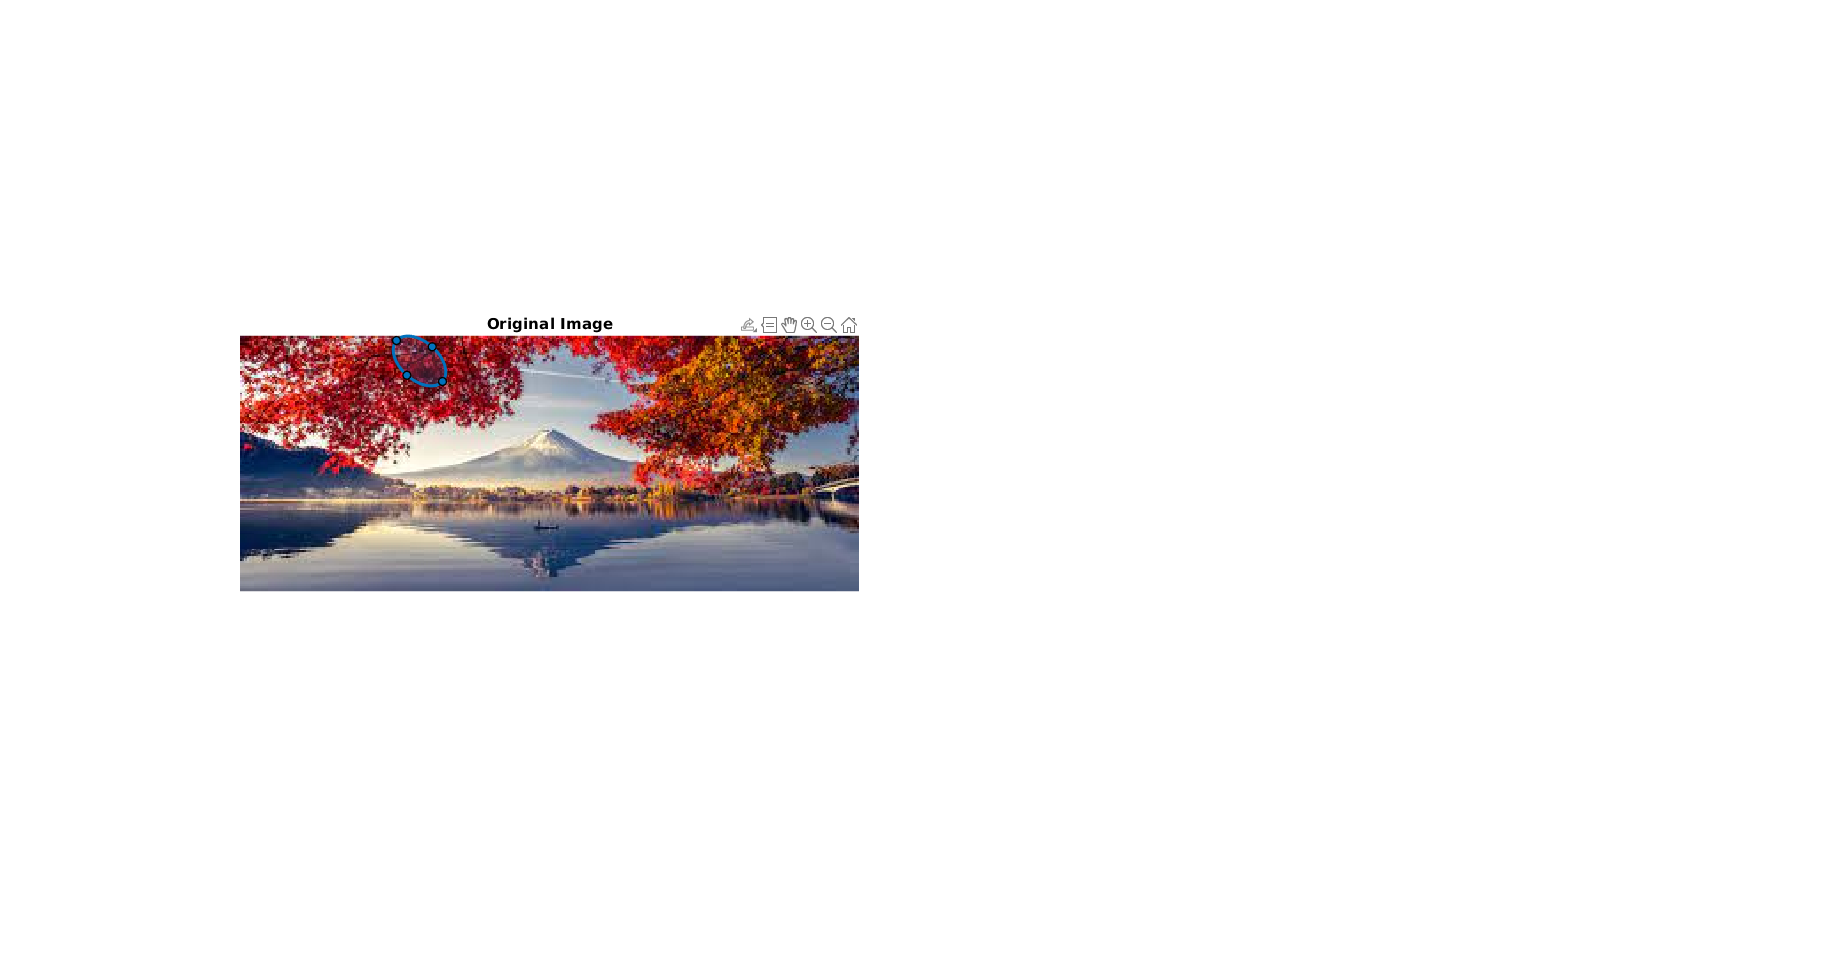

% Clear any existing variables, the command window, and the figure windows.
clear;
clc;
close all;

% Load the image.
% [imageName, imagePath] = uigetfile({'*.tiff;*.jpg;*.png;*.jpeg'}, "select an image");
% original = imread(strcat(imagePath, imageName));
original = imread('images/download.jpeg');
figure('units','normalized','outerposition',[0 0 1 1])
% Prompt the user to select the mask.
[binaryImage, original] = createMaskv2(original);

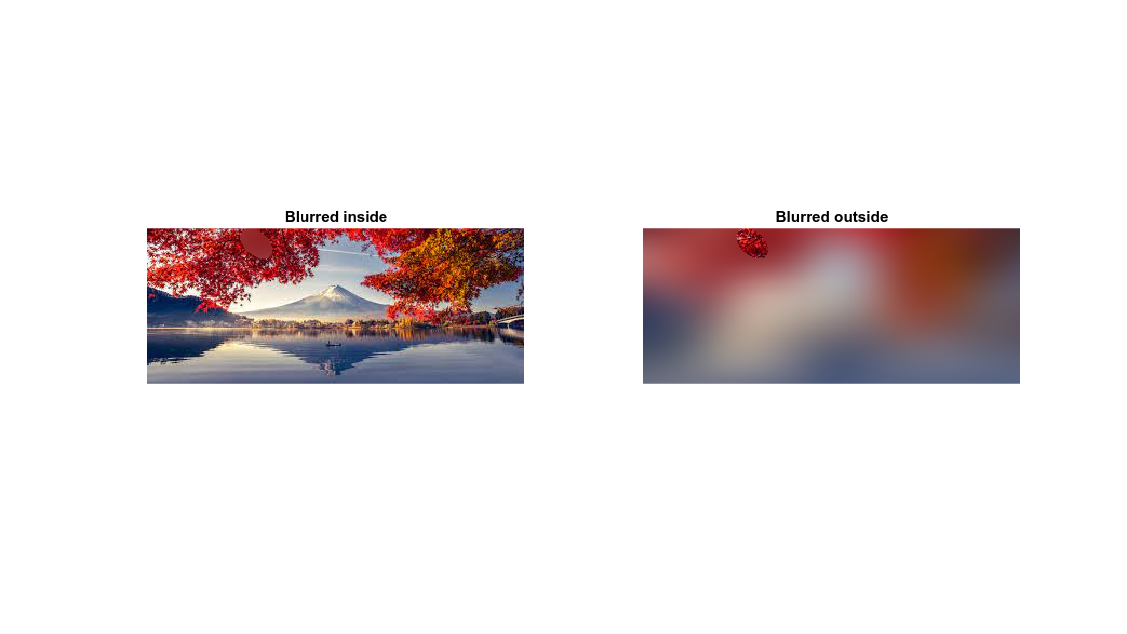

% blurImagev2 blurs an image both inside and outside a binary mask and displays the result
figure('units','normalized','outerposition',[0 0 1 1])
blurImagev2(original, binaryImage)

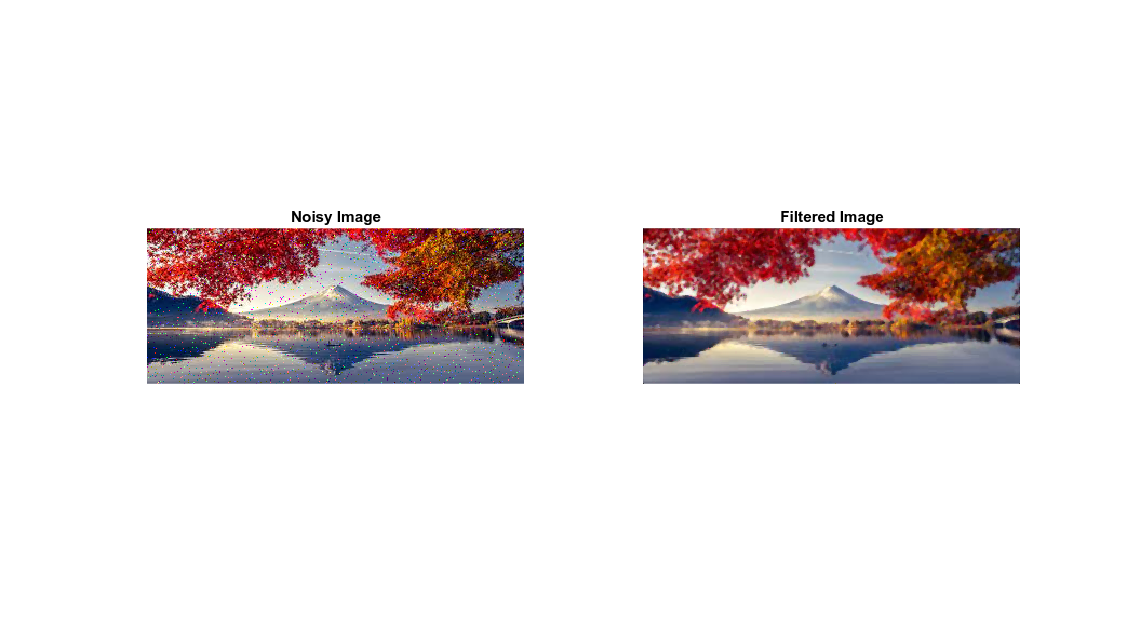

figure('units','normalized','outerposition',[0 0 1 1])
% SaltAndPepperNoiseReductionv2 adds salt and pepper noise to the image and
% removes it using the median filter
SaltAndPepperNoiseReductionv2(original)

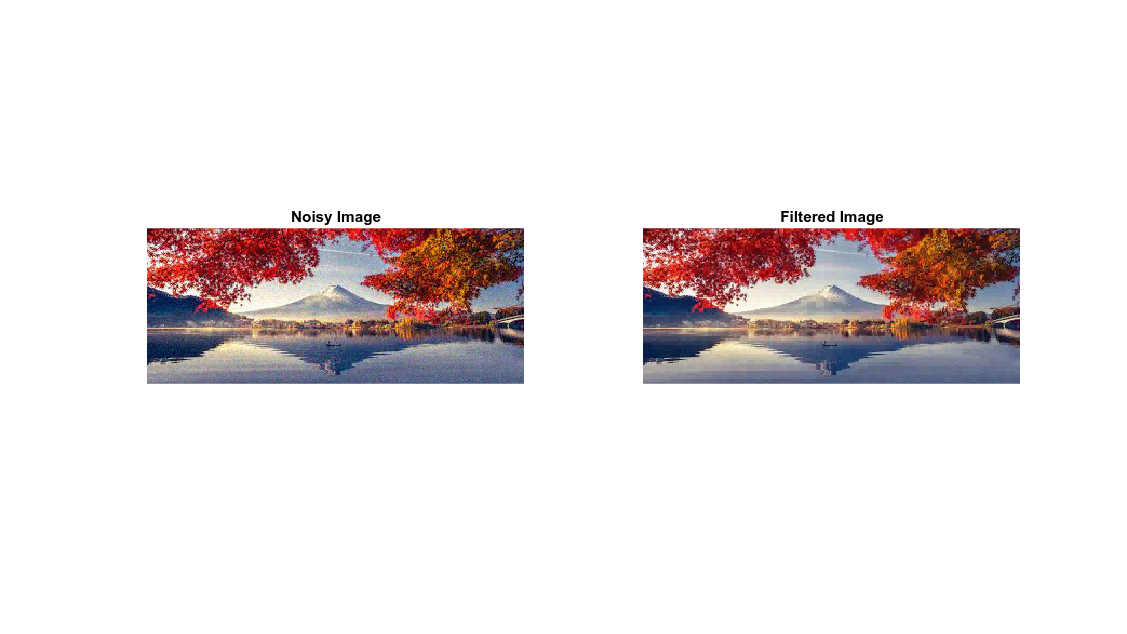

figure('units','normalized','outerposition',[0 0 1 1])
% GaussianNoiseReductionv2 add gaussian noise (mean 0.010,variance 0.002) to
% the image and  use the Haar wavelet for denoising it.
GaussianNoiseReductionv2(original)

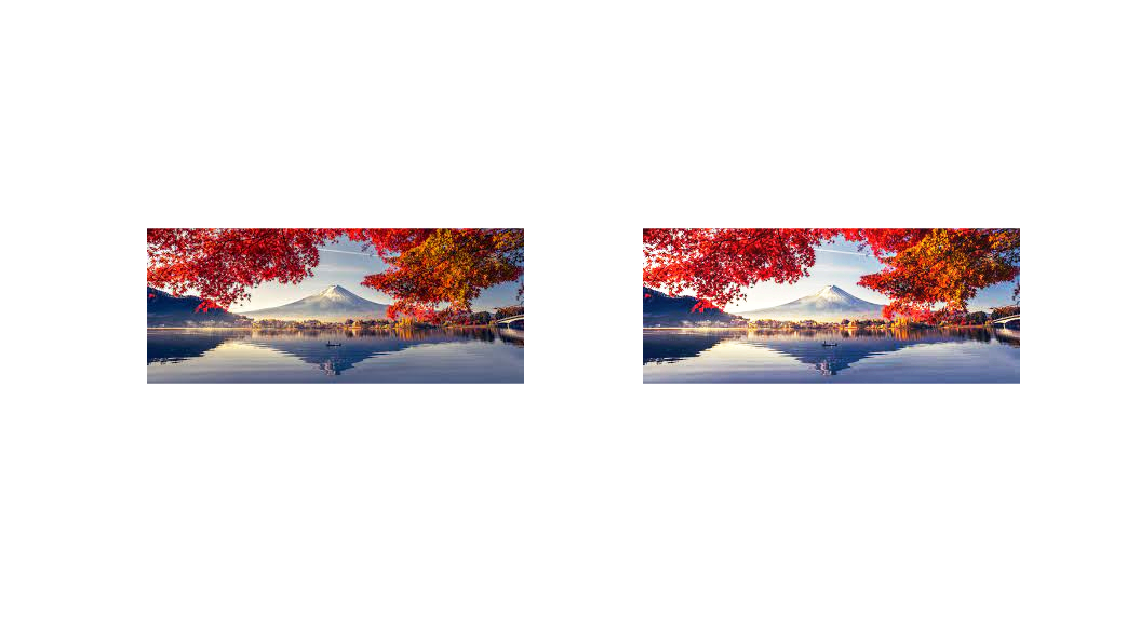

figure('units','normalized','outerposition',[0 0 1 1])
% histogramEqualization performs the histogram equalization
histogramEqualization(original)

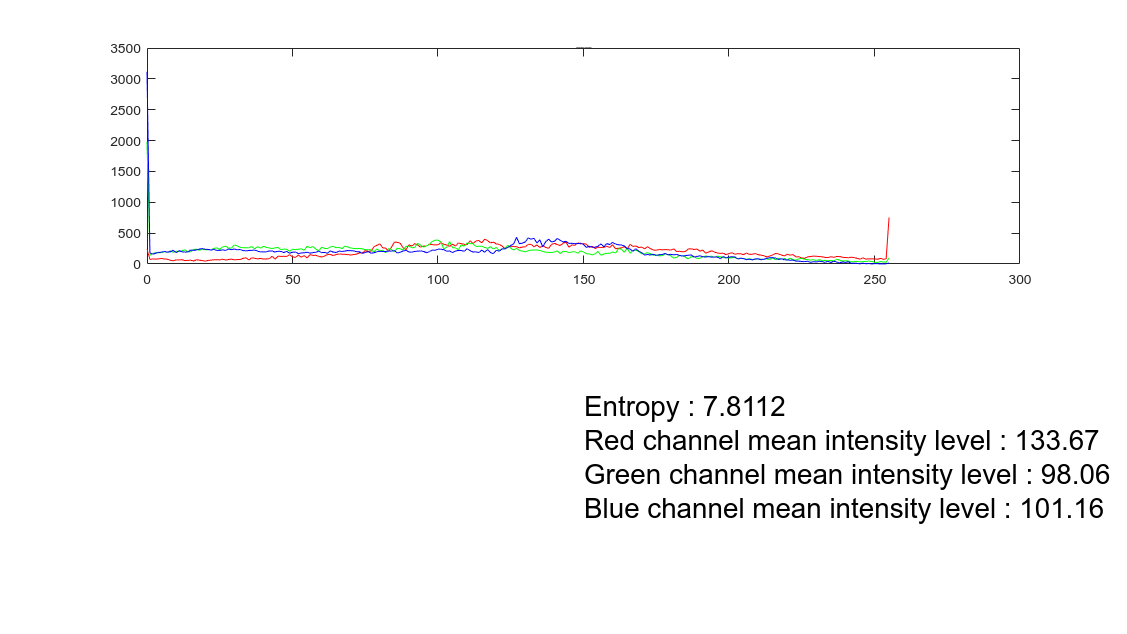

figure('units','normalized','outerposition',[0 0 1 1])
% imageInformationsv2 displays and analyzes various image proprieties such as
% histograms, mean intensity level, and entropy.
% in case of RGB image returns the above informations for all channels
imageInformationsv2(original)